Select source data folder. Data folder shold have the following structure:

src_data

----damaged

----healthy

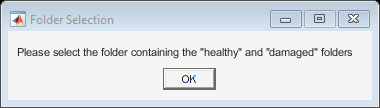

fileStruct = struct with fields:
    healthy: {1×19 cell}
    damaged: [1×1 struct]


fileStruct = struct with fields:
    healthy: {1×19 cell}
    damaged: [1×1 struct]


fileStruct = struct with fields:
    healthy: {1×19 cell}
    damaged: [1×1 struct]


fileStruct = struct with fields:
    healthy: {1×19 cell}
    damaged: [1×1 struct]


fileStruct = struct with fields:
    healthy: {1×19 cell}
    damaged: [1×1 struct]


[fileStruct, folderPathStruct] = selectFolderAndListFiles();

fileStruct: struct with the filenames of each folder ("healthy" and "damaged").

folderPath: absolute path of where folders "healthy" and "damaged" are located.

%%%%%%%%%%%

If "`Error using processTDMSFiles Specified TDMS file might be unsupported v1.0`"

Use the the live script **tscm.data_conversion.mlx**

%%%%%%%%%%%

%fileList_healthy = fileStruct.healthy;
%fileList_damaged_GF = fileStruct.damaged.GF_Ritzel;
%fileList_damaged_SIZA = fileStruct.damaged.SIZA_Graufleckigkeit_Ritzel_und_Rad;
fileList_damaged_Gruebchen_Ritzel_Rad_leicht = fileStruct.damaged.Gruebchen_Ritzel_Rad_leicht;
fileList_damaged_Graufleckigkeit_Ritzel_schwer_Rad_leicht = fileStruct.damaged.Graufleckigkeit_Ritzel_schwer_Rad_leicht;
fileList_damaged_Verschleiss_Ritzel_Rad_mittel = fileStruct.damaged.Verschleiss_Ritzel_Rad_mittel;

The struct has been divided in two lists, which are going to be converted into a struct of tables containing all files

decimateFactor = 10;

%tdmsTables_healthy = processTDMSFiles(fileList_healthy, folderPathStruct.healthy, decimateFactor);
%tdmsTables_damaged_GF = processTDMSFiles(fileList_damaged_GF, folderPathStruct.damaged.GF_Ritzel, decimateFactor);

G:\Semester Arbeit\Programming\data\converted_data\healthy\24-02-15-16-46-40-112_5_500Nm__200_rpm.tdms
G:\Semester Arbeit\Programming\data\converted_data\healthy\24-02-15-17-10-46-112_5_500_Nm_1200_rrpm.tdms
G:\Semester Arbeit\Programming\data\converted_data\healthy\24-03-25-15-19-25-112_5_500_Nm_400_rpm.tdms
G:\Semester Arbeit\Programming\data\converted_data\healthy\24-03-25-15-28-45-112_5_500_Nm_800_rpm.tdms
G:\Semester Arbeit\Programming\data\converted_data\healthy\24-03-25-15-32-55-112_5_500_Nm_1000_rpm.tdms
G:\Semester Arbeit\Programming\data\converted_data\healthy\24-03-25-15-36-48-112_5_500_Nm_1200_rpm.tdms
G:\Semester Arbeit\Programming\data\converted_data\healthy\24-03-25-15-58-41-112_5_500_Nm_1900_2000_rpm.tdms
G:\Semester Arbeit\Programming\data\converted_data\healthy\24-03-25-16-03-14-112_5_500_Nm_2200_rpm.tdms
G:\Semester Arbeit\Programming\data\converted_data\healthy\24-03-25-16-06-46-112_5_500_Nm_2400_rpm.tdms
G:\Semester Arbeit\Programming\data\converted_data\healthy\24

%tdmsTables_damaged_SIZA = processTDMSFiles(fileList_damaged_SIZA, folderPathStruct.damaged.SIZA_Graufleckigkeit_Ritzel_und_Rad, decimateFactor);

G:\Semester Arbeit\Programming\data\converted_data\damaged\GF_Ritzel\24-06-10-10-33-51-112_5_300_Nm_500_rpm_GF_Ritzel.tdms
G:\Semester Arbeit\Programming\data\converted_data\damaged\GF_Ritzel\24-06-10-10-39-47-112_5_300_Nm_1000_rpm_GF_Ritzel.tdms
G:\Semester Arbeit\Programming\data\converted_data\damaged\GF_Ritzel\24-06-10-10-42-00-112_5_300_Nm_1500_rpm_GF_Ritzel.tdms
G:\Semester Arbeit\Programming\data\converted_data\damaged\GF_Ritzel\24-06-10-10-44-02-112_5_300_Nm_2000_rpm_GF_Ritzel.tdms
G:\Semester Arbeit\Programming\data\converted_data\damaged\GF_Ritzel\24-06-10-10-45-48-112_5_300_Nm_2500_rpm_GF_Ritzel.tdms
G:\Semester Arbeit\Programming\data\converted_data\damaged\GF_Ritzel\24-06-10-10-46-55-112_5_300_Nm_2500_rpm_GF_Ritzel.tdms
G:\Semester Arbeit\Programming\data\converted_data\damaged\GF_Ritzel\24-06-10-10-48-35-112_5_300_Nm_3000_rpm_GF_Ritzel.tdms
G:\Semester Arbeit\Programming\data\converted_data\damaged\GF_Ritzel\24-06-10-11-04-36-112_5_500_Nm_500_rpm_GF_Ritzel.tdms
G:\Semeste

tdmsTables_damaged_Gruebchen_Ritzel_Rad_leicht = processTDMSFiles(fileList_damaged_SIZA, folderPathStruct.damaged.SIZA_Graufleckigkeit_Ritzel_und_Rad, decimateFactor);
tdmsTables_damaged_Graufleckigkeit_Ritzel_schwer_Rad_leicht = processTDMSFiles(fileList_damaged_SIZA, folderPathStruct.damaged.SIZA_Graufleckigkeit_Ritzel_und_Rad, decimateFactor);
tdmsTables_damaged_Verschleiss_Ritzel_Rad_mittel = processTDMSFiles(fileList_damaged_SIZA, folderPathStruct.damaged.SIZA_Graufleckigkeit_Ritzel_und_Rad, decimateFactor);

%tableFeatures_healthy = extractTableFeatures(tdmsTables_healthy);
%tableFeatures_damaged_GF = extractTableFeatures(tdmsTables_damaged_GF);
%tableFeatures_damaged_SIZA = extractTableFeatures(tdmsTables_damaged_SIZA);
tableFeatures_damaged_Gruebchen_Ritzel_Rad_leicht = extractTableFeatures(tdmsTables_damaged_Gruebchen_Ritzel_Rad_leicht);
tableFeatures_damaged_Graufleckigkeit_Ritzel_schwer_Rad_leicht = extractTableFeatures(tdmsTables_damaged_Graufleckigkeit_Ritzel_schwer_Rad_leicht);
tableFeatures_damaged_Verschleiss_Ritzel_Rad_mittel = extractTableFeatures(tdmsTables_damaged_Verschleiss_Ritzel_Rad_mittel);

%exportTableToCSV(tableFeatures_healthy);

%exportTableToCSV(tableFeatures_damaged_GF);

%exportTableToCSV(tableFeatures_damaged_SIZA);

exportTableToCSV(tableFeatures_damaged_Gruebchen_Ritzel_Rad_leicht);

Table successfully exported to G:\Semester Arbeit\Programming\notebooks\csv_files\exported_table_healthy_fs_10kHz.csv


exportTableToCSV(tableFeatures_damaged_Graufleckigkeit_Ritzel_schwer_Rad_leicht);

Table successfully exported to G:\Semester Arbeit\Programming\notebooks\csv_files\exported_table_damaged_fs_10kHz.csv


exportTableToCSV(tableFeatures_damaged_Verschleiss_Ritzel_Rad_mittel);